# Graficas de comparativas de los controladores

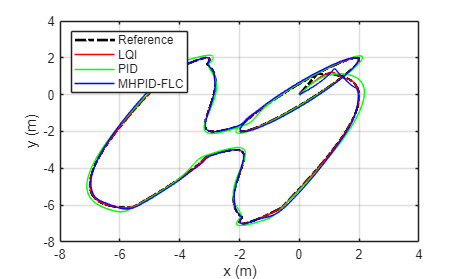

clear, clc, close all

% DATOS
load("r_lqi.mat")
load("r_pid.mat")
load("r_mhpid.mat")

controladores = {'LQI','PID','MHPID-FLC'};
R = {r_lqi, r_pid, r_mhpid};

% TIEMPO
n_points = min([length(r_lqi.Time), length(r_pid.Time), length(r_mhpid.Time)]);
t_common = linspace(0,100,n_points);

% REFERENCIA
x_ref = -0.5*max(0,min(t_common-25,10)) + 0.5*max(0,min(t_common-55,10)) ...
        - 2*sin(0.1*pi.*t_common + 0.3).*(t_common>=10);
y_ref = -0.5*max(0,min(t_common-10,10)) + 0.5*max(0,min(t_common-40,10)) ...
        - 2*sin(0.1*pi.*t_common + 0.6).*(t_common>=10);
z_ref = 1.5 + 0.1*sin(0.02*pi.*t_common + 0.3).*(t_common>=10);

figure
plot(x_ref,y_ref,'LineStyle','-.','LineWidth',2,'Color','black')
grid on
hold on
plot(r_lqi.Data(1,:), r_lqi.Data(2,:),'Color','r')
plot(r_pid.Data(1,:), r_pid.Data(2,:),'Color','g')
plot(r_mhpid.Data(1,:), r_mhpid.Data(2,:),'Color','b')

legend('Reference', 'LQI', 'PID', 'MHPID-FLC', 'Location','northwest')
xlabel('x (m)')
ylabel('y (m)')

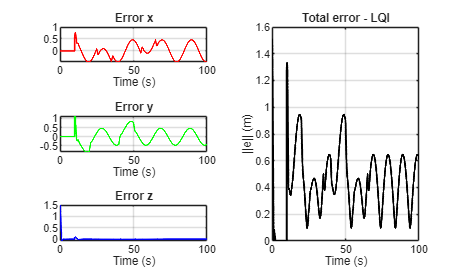

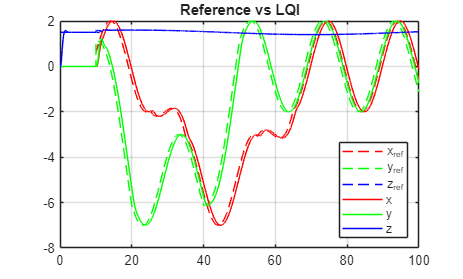

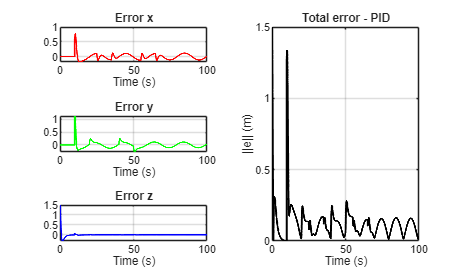

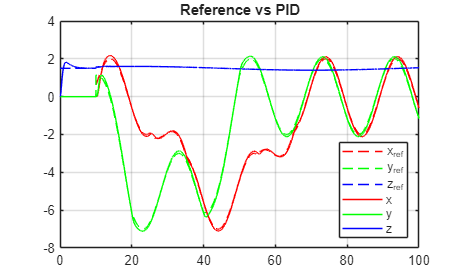

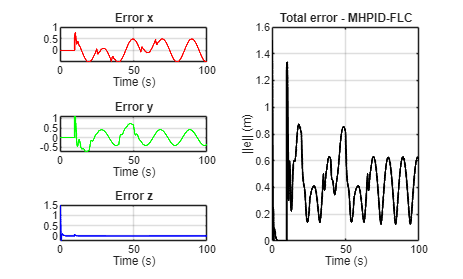

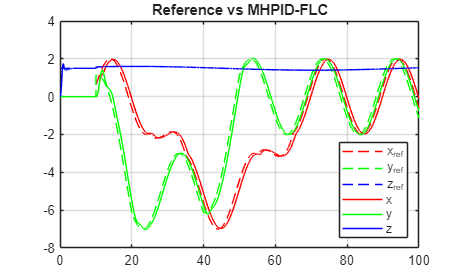


ITAE_all = zeros(3,3); % ITAE por eje
ITVAE_all = zeros(3,1); % ITVAE global

for i = 1:3
    
    a = R{i};
    ti = controladores{i};
    
    % INTERPOLAR DATOS
    x_data = interp1(a.Time, a.Data(1,:), t_common, 'linear'); 
    y_data = interp1(a.Time, a.Data(2,:), t_common, 'linear'); 
    z_data = interp1(a.Time, a.Data(3,:), t_common, 'linear');     
    
    x_ref = x_ref(:); y_ref = y_ref(:); z_ref = z_ref(:);
    x_data = x_data(:); y_data = y_data(:); z_data = z_data(:);
    
    % ERROR
    e = [x_ref - x_data, y_ref - y_data, z_ref - z_data];
    e_norm = sqrt(sum(e.^2,2)); % norma
    
    t_col = t_common(:);
    
    % ÍNDICES DE DESEMPEÑO
    ITAE = trapz(t_col, t_col .* abs(e));   % Nx1 .* Nx3 = Nx3 → ITAE por eje
    ITVAE = trapz(t_col, t_col .* e_norm);  % Nx1 .* Nx1 → ITVAE global
    
    ITAE_all(i,:) = ITAE;
    ITVAE_all(i) = ITVAE;
    
    figure
    tiledlayout(3,2)

    nexttile(1)
    plot(t_common, e(:,1),'r','LineWidth',1.2)
    grid on
    title('Error x')
    xlabel('Time (s)')
    %ylabel('Error (m)')

    nexttile(3)
    plot(t_common, e(:,2),'g','LineWidth',1.2)
    grid on
    title('Error y')
    xlabel('Time (s)')
    %ylabel('Error (m)')

    nexttile(5)
    plot(t_common, e(:,3),'b','LineWidth',1.2)
    grid on
    title('Error z')
    xlabel('Time (s)')
    %ylabel('Error (m)')

    % NORMA
    nexttile([3 1])
    plot(t_common, e_norm,'k','LineWidth',1.5)
    grid on
    title(['Total error - ' ti])
    xlabel('Time (s)')
    ylabel('||e|| (m)')
    
    figure
    plot(t_common,x_ref,'--r', ...
        t_common,y_ref,'--g', ...
        t_common,z_ref,'--b')
    hold on
    grid on
    plot(t_common,x_data,'r', ...
        t_common,y_data,'g', ...
        t_common,z_data,'b')
    title(['Reference vs ' ti])
    legend('x_{ref}', 'y_{ref}', 'z_{ref}', 'x', 'y', 'z', 'Location','southeast')
end

## Perturbacion

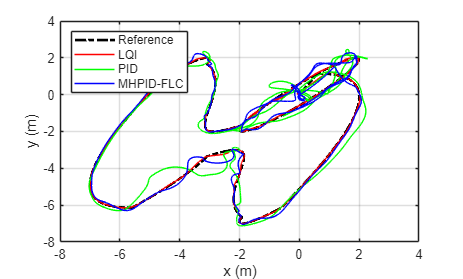

load("r_lqi_p.mat")
load("r_pid_p.mat")
load("r_mhpid_p.mat")

R = {r_lqi_p, r_pid_p, r_mhpid_p};

% TIEMPO
n_points = min([length(r_lqi_p.Time), length(r_pid_p.Time), length(r_mhpid_p.Time)]);
t_common = linspace(0,100,n_points);

% REFERENCIA
x_ref = -0.5*max(0,min(t_common-25,10)) + 0.5*max(0,min(t_common-55,10)) ...
        - 2*sin(0.1*pi.*t_common + 0.3).*(t_common>=10);
y_ref = -0.5*max(0,min(t_common-10,10)) + 0.5*max(0,min(t_common-40,10)) ...
        - 2*sin(0.1*pi.*t_common + 0.6).*(t_common>=10);
z_ref = 1.5 + 0.1*sin(0.02*pi.*t_common + 0.3).*(t_common>=10);

figure
plot(x_ref,y_ref,'LineStyle','-.','LineWidth',2,'Color','black')
grid on
hold on
plot(r_lqi_p.Data(1,:), r_lqi_p.Data(2,:),'Color','r')
plot(r_pid_p.Data(1,:), r_pid_p.Data(2,:),'Color','g')
plot(r_mhpid_p.Data(1,:), r_mhpid_p.Data(2,:),'Color','b')

legend('Reference', 'LQI', 'PID', 'MHPID-FLC', 'Location','northwest')
xlabel('x (m)')
ylabel('y (m)')

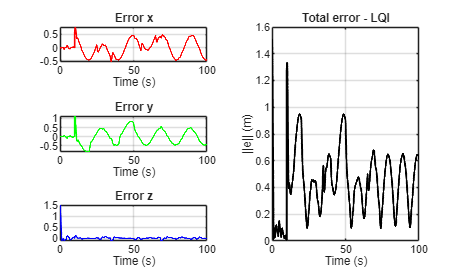

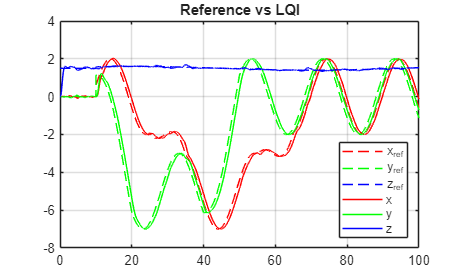

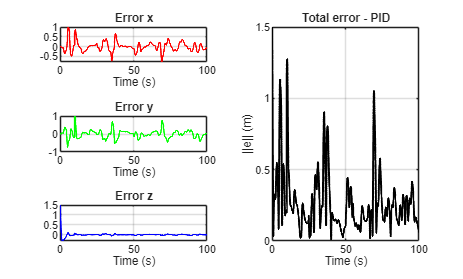

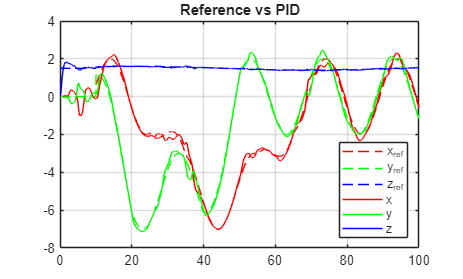

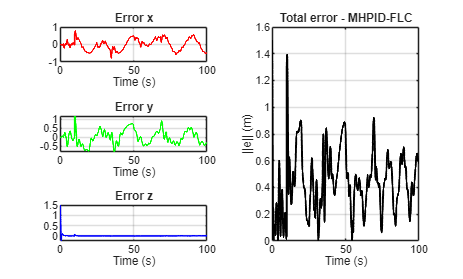

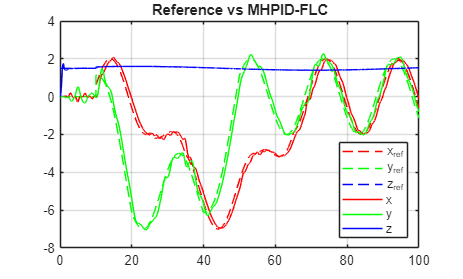


ITAE_all = zeros(3,3); % ITAE por eje
ITVAE_all = zeros(3,1); % ITVAE global

for i = 1:3
    
    a = R{i};
    ti = controladores{i};
    
    % INTERPOLAR DATOS
    x_data = interp1(a.Time, a.Data(1,:), t_common, 'linear'); 
    y_data = interp1(a.Time, a.Data(2,:), t_common, 'linear'); 
    z_data = interp1(a.Time, a.Data(3,:), t_common, 'linear'); 
    
    x_ref = x_ref(:); y_ref = y_ref(:); z_ref = z_ref(:);
    x_data = x_data(:); y_data = y_data(:); z_data = z_data(:);
    
    % ERROR
    e = [x_ref - x_data, y_ref - y_data, z_ref - z_data];
    e_norm = sqrt(sum(e.^2,2)); % norma
    
    t_col = t_common(:);
    
    % ÍNDICES DE DESEMPEÑO
    ITAE = trapz(t_col, abs(e));   % Nx1 .* Nx3 = Nx3 → ITAE por eje
    ITVAE = trapz(t_col, e_norm);  % Nx1 .* Nx1 → ITVAE global
    
    ITAE_all(i,:) = ITAE;
    ITVAE_all(i) = ITVAE;
    
    figure
    tiledlayout(3,2)

    nexttile(1)
    plot(t_common, e(:,1),'r','LineWidth',1.2)
    grid on
    title('Error x')
    xlabel('Time (s)')
    %ylabel('Error (m)')

    nexttile(3)
    plot(t_common, e(:,2),'g','LineWidth',1.2)
    grid on
    title('Error y')
    xlabel('Time (s)')
    %ylabel('Error (m)')

    nexttile(5)
    plot(t_common, e(:,3),'b','LineWidth',1.2)
    grid on
    title('Error z')
    xlabel('Time (s)')
    %ylabel('Error (m)')

    % NORMA
    nexttile([3 1])
    plot(t_common, e_norm,'k','LineWidth',1.5)
    grid on
    title(['Total error - ' ti])
    xlabel('Time (s)')
    ylabel('||e|| (m)')
    
    figure
    plot(t_common,x_ref,'--r', ...
        t_common,y_ref,'--g', ...
        t_common,z_ref,'--b')
    hold on
    grid on
    plot(t_common,x_data,'r', ...
        t_common,y_data,'g', ...
        t_common,z_data,'b')
    title(['Reference vs ' ti])
    legend('x_{ref}', 'y_{ref}', 'z_{ref}', 'x', 'y', 'z', 'Location','southeast')
end


% % ITAE por eje
% figure
% bar(ITAE_all')
% grid on
% title('Comparación ITAE por eje')
% legend(controladores,'Location','northwest')
% xlabel('Eje')
% ylabel('ITAE')
% set(gca,'XTickLabel',{'x','y','z'})
% 
% %ITVAE global
% figure
% bar(ITVAE_all)
% grid on
% title('Comparación ITVAE (error global)')
% set(gca,'XTickLabel',controladores)
% ylabel('ITVAE')